# Example 4.7: Simulating the Central Limit Theorem

Note: this script reproduces Example 4.7 (Section 4.3.3) of **Statistics for Chemical Engineers**: the distribution of the sample average of Weibull(1,2) observations. Victor Z UW-Madison, 2020 simulating the central limit theorem (clt)

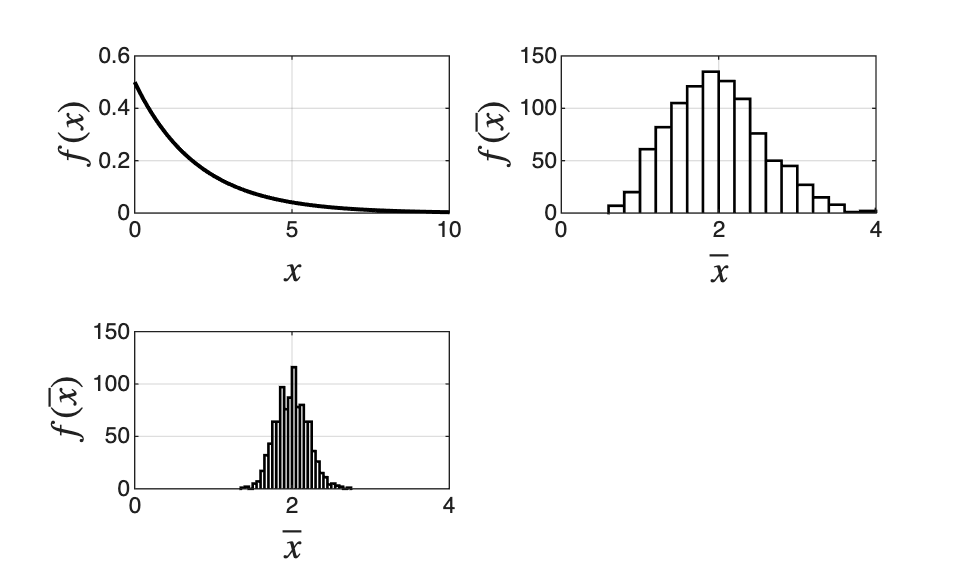

clc; clear all; close all hidden; format short e;

rng(0);
N=1000;  % number of samples

figure(1)
subplot(2,2,1)
xgrid=linspace(0,10,1000);
plot(xgrid,wblpdf(xgrid,2,1),'black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on

S=10; % sample size
for j=1:N
    x = wblrnd(2,1,S,1);
    m(j) = mean(x);
end

subplot(2,2,2)
histogram(m,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$\bar{x}$','Interpreter','latex','FontSize',14)
ylabel('$f(\bar{x})$','Interpreter','latex','FontSize',14)
grid on
axis([0 4 0 150])

S=100;  % number of samples
for j=1:N
    x = wblrnd(2,1,S,1);
    m(j) = mean(x);
end
subplot(2,2,3)
histogram(m,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$\bar{x}$','Interpreter','latex','FontSize',14)
ylabel('$f(\bar{x})$','Interpreter','latex','FontSize',14)
grid on
axis([0 4 0 150])


S=1000;  % number of samples
for j=1:N
    x = wblrnd(2,1,S,1);
    m(j) = mean(x);
end

## Variance of the sample average (batching)

estimate variance of sample estimate using batching

mb=mean(m);
vestS=(1/N)*sum((m-mb).^2)

vestS =    3.8347e-03

vest=vestS*S

vest =    3.8347e+00

## True mean and variance

real mean and variance of RV

[mm,vv]=wblstat(2,1)

mm =      2

vv =      4

## Gaussian fit

obtain mean and variance from Gaussian fit

pd = fitdist(m','Normal')

pd =   NormalDistribution

  Normal distribution
       mu =   1.99682   [1.99297, 2.00066]
    sigma = 0.0619557   [0.0593543, 0.0647973]


v2s=pd.sigma^2

v2s =    3.8385e-03

v2=v2s*S

v2 =    3.8385e+00

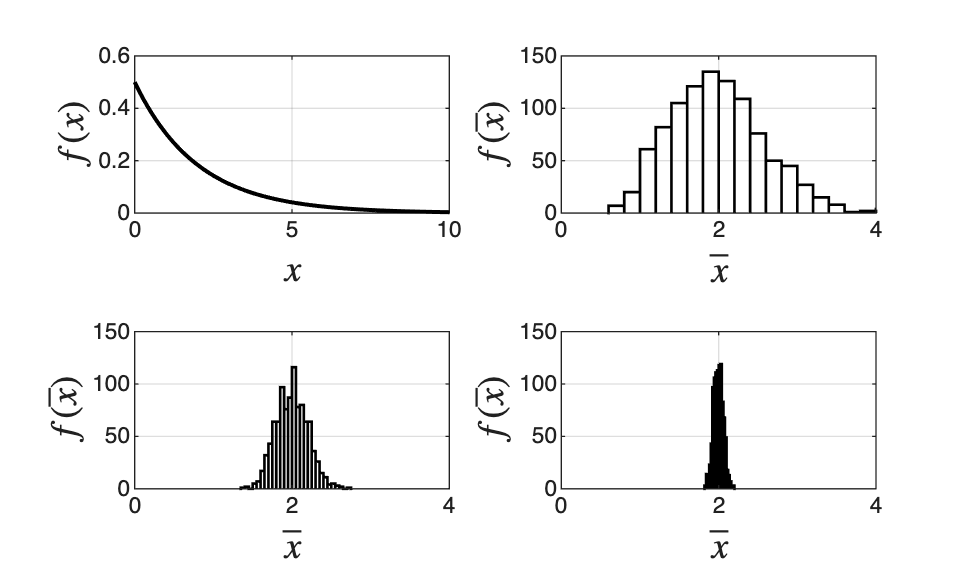


subplot(2,2,4)
histogram(m,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$\bar{x}$','Interpreter','latex','FontSize',14)
ylabel('$f(\bar{x})$','Interpreter','latex','FontSize',14)
grid on
axis([0 4 0 150])

print -depsc ch4_clt_weibull.eps

## Note

As in the book, the sample average is Gaussian even though X is not, and its variance shrinks with S: this is the central limit theorem.